% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 15;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-08-09/";

% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

% Sample A data

file_name = "Blood_Plasma1(40x,495mW,A)_2000_30_2024-08-09-12.09.32.687.csv";
file_path = data_path+file_name;
blood_1_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,A)_2000_30_2024-08-09-12.11.14.140.csv";
file_path = strcat(data_path,file_name);
blood_2_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,A)_2000_30_2024-08-09-12.12.39.517.csv";
file_path = strcat(data_path,file_name);
blood_3_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,A)_2000_30_2024-08-09-12.14.03.367.csv";
file_path = strcat(data_path,file_name);
blood_4_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,A)_2000_30_2024-08-09-12.15.28.997.csv";
file_path = strcat(data_path,file_name);
blood_5_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,A)_2000_30_2024-08-09-12.16.56.707.csv";
file_path = strcat(data_path,file_name);
blood_6_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,A)_2000_30_2024-08-09-12.18.22.553.csv";
file_path = strcat(data_path,file_name);
blood_7_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,A)_2000_30_2024-08-09-12.19.55.947.csv";
file_path = strcat(data_path,file_name);
blood_8_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,A)_2000_30_2024-08-09-12.21.21.380.csv";
file_path = strcat(data_path,file_name);
blood_9_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,A)_2000_30_2024-08-09-12.22.50.393.csv";
file_path = strcat(data_path,file_name);
blood_10_A8 = csvread(file_path, numMetadataRows, 0);

% Sample B data

file_name = "Blood_Plasma1(40x,495mW,B)_2000_30_2024-08-09-12.33.40.867.csv";
file_path = data_path+file_name;
blood_1_B8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,B)_2000_30_2024-08-09-12.35.12.713.csv";
file_path = strcat(data_path,file_name);
blood_2_B8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,B)_2000_30_2024-08-09-12.36.41.973.csv";
file_path = strcat(data_path,file_name);
blood_3_B8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,B)_2000_30_2024-08-09-12.38.08.400.csv";
file_path = strcat(data_path,file_name);
blood_4_B8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,B)_2000_30_2024-08-09-12.39.33.217.csv";
file_path = strcat(data_path,file_name);
blood_5_B8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,B)_2000_30_2024-08-09-12.41.02.903.csv";
file_path = strcat(data_path,file_name);
blood_6_B8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,B)_2000_30_2024-08-09-12.42.32.927.csv";
file_path = strcat(data_path,file_name);
blood_7_B8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,B)_2000_30_2024-08-09-12.43.56.673.csv";
file_path = strcat(data_path,file_name);
blood_8_B8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,B)_2000_30_2024-08-09-12.45.26.250.csv";
file_path = strcat(data_path,file_name);
blood_9_B8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,B)_2000_30_2024-08-09-12.46.52.257.csv";
file_path = strcat(data_path,file_name);
blood_10_B8 = csvread(file_path, numMetadataRows, 0);

file_name = "NIST(40x,495mW)_50_250_2024-08-09-11.32.18.683.csv";
file_path = strcat(data_path,file_name);
NISTspectrum = csvread(file_path, numMetadataRows, 0);

file_name = "Polystyrene(40x,495mW)_60_250_2024-08-09-11.27.43.780.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_50_250_2024-08-09-11.22.46.103.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1_A8(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;

wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];

blood_1_A8(:, blood_1_A8(1, :) <= t1) = [];
blood_1_A8(:, blood_1_A8(1, :) >= t2) = [];
blood_2_A8(:, blood_2_A8(1, :) <= t1) = [];
blood_2_A8(:, blood_2_A8(1, :) >= t2) = [];
blood_3_A8(:, blood_3_A8(1, :) <= t1) = [];
blood_3_A8(:, blood_3_A8(1, :) >= t2) = [];
blood_4_A8(:, blood_4_A8(1, :) <= t1) = [];
blood_4_A8(:, blood_4_A8(1, :) >= t2) = [];
blood_5_A8(:, blood_5_A8(1, :) <= t1) = [];
blood_5_A8(:, blood_5_A8(1, :) >= t2) = [];
blood_6_A8(:, blood_6_A8(1, :) <= t1) = [];
blood_6_A8(:, blood_6_A8(1, :) >= t2) = [];
blood_7_A8(:, blood_7_A8(1, :) <= t1) = [];
blood_7_A8(:, blood_7_A8(1, :) >= t2) = [];
blood_8_A8(:, blood_8_A8(1, :) <= t1) = [];
blood_8_A8(:, blood_8_A8(1, :) >= t2) = [];
blood_9_A8(:, blood_9_A8(1, :) <= t1) = [];
blood_9_A8(:, blood_9_A8(1, :) >= t2) = [];
blood_10_A8(:, blood_10_A8(1, :) <= t1) = [];
blood_10_A8(:, blood_10_A8(1, :) >= t2) = [];

blood_1_B8(:, blood_1_B8(1, :) <= t1) = [];
blood_1_B8(:, blood_1_B8(1, :) >= t2) = [];
blood_2_B8(:, blood_2_B8(1, :) <= t1) = [];
blood_2_B8(:, blood_2_B8(1, :) >= t2) = [];
blood_3_B8(:, blood_3_B8(1, :) <= t1) = [];
blood_3_B8(:, blood_3_B8(1, :) >= t2) = [];
blood_4_B8(:, blood_4_B8(1, :) <= t1) = [];
blood_4_B8(:, blood_4_B8(1, :) >= t2) = [];
blood_5_B8(:, blood_5_B8(1, :) <= t1) = [];
blood_5_B8(:, blood_5_B8(1, :) >= t2) = [];
blood_6_B8(:, blood_6_B8(1, :) <= t1) = [];
blood_6_B8(:, blood_6_B8(1, :) >= t2) = [];
blood_7_B8(:, blood_7_B8(1, :) <= t1) = [];
blood_7_B8(:, blood_7_B8(1, :) >= t2) = [];
blood_8_B8(:, blood_8_B8(1, :) <= t1) = [];
blood_8_B8(:, blood_8_B8(1, :) >= t2) = [];
blood_9_B8(:, blood_9_B8(1, :) <= t1) = [];
blood_9_B8(:, blood_9_B8(1, :) >= t2) = [];
blood_10_B8(:, blood_10_B8(1, :) <= t1) = [];
blood_10_B8(:, blood_10_B8(1, :) >= t2) = [];


shifts = wavenumber;

blood1_A8 = blood_1_A8(2:end, :);
blood2_A8 = blood_2_A8(2:end, :);
blood3_A8 = blood_3_A8(2:end, :);
blood4_A8 = blood_4_A8(2:end, :);
blood5_A8 = blood_5_A8(2:end, :);
blood6_A8 = blood_6_A8(2:end, :);
blood7_A8 = blood_7_A8(2:end, :);
blood8_A8 = blood_8_A8(2:end, :);
blood9_A8 = blood_9_A8(2:end, :);
blood10_A8 = blood_10_A8(2:end, :);

blood1_B8 = blood_1_B8(2:end, :);
blood2_B8 = blood_2_B8(2:end, :);
blood3_B8 = blood_3_B8(2:end, :);
blood4_B8 = blood_4_B8(2:end, :);
blood5_B8 = blood_5_B8(2:end, :);
blood6_B8 = blood_6_B8(2:end, :);
blood7_B8 = blood_7_B8(2:end, :);
blood8_B8 = blood_8_B8(2:end, :);
blood9_B8 = blood_9_B8(2:end, :);
blood10_B8 = blood_10_B8(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

## Blood Plasma Well Trial 2024-08-09, 2x D227 150μL Sample

- Data from each well is shown, including raw data in the first plot from each section, group processed data in the second plot, and individually processed data by trial in the third plot.

- The sample was prepared by removing from the freezer, rocking for 35 minutes, and then rested for 7 minutes in the well slide.

- Samples were pipetted into 3 50μL wells and then covered with a 22mmx22mm No. 1 Cover Glass slip.

- Data was taken using a 40x immersion objective lens by using a dropper bottle to place water on the cover glass slip atop the well slide then immersing the lens in the water drop, then focusing the objective over each well using a motorized XYZ stage.

- In the 'group processed' plots, an array was made combining data from all trials in that well, and then the 'apply' function was used for processing.

- In the 'individual processing' plots, the 'apply' function was used individually on each trial, and then the resulting pre-processed data was then plotted together in a figure.

# Sample A Data

% Plotting unprocessed data

colors = [
    0.94, 0.80, 0.91; % Lavender Blush
    0.87, 0.63, 0.87; % Thistle
    0.80, 0.40, 0.80; % Orchid
    0.73, 0.33, 0.83; % Amethyst
    0.69, 0.19, 0.38; % Plum
    0.58, 0.00, 0.83; % Dark Violet
    0.50, 0.00, 0.50; % Purple
    0.48, 0.25, 0.52; % Blue Violet
    0.41, 0.16, 0.38; % Dark Orchid
    0.36, 0.15, 0.53  % Indigo
];


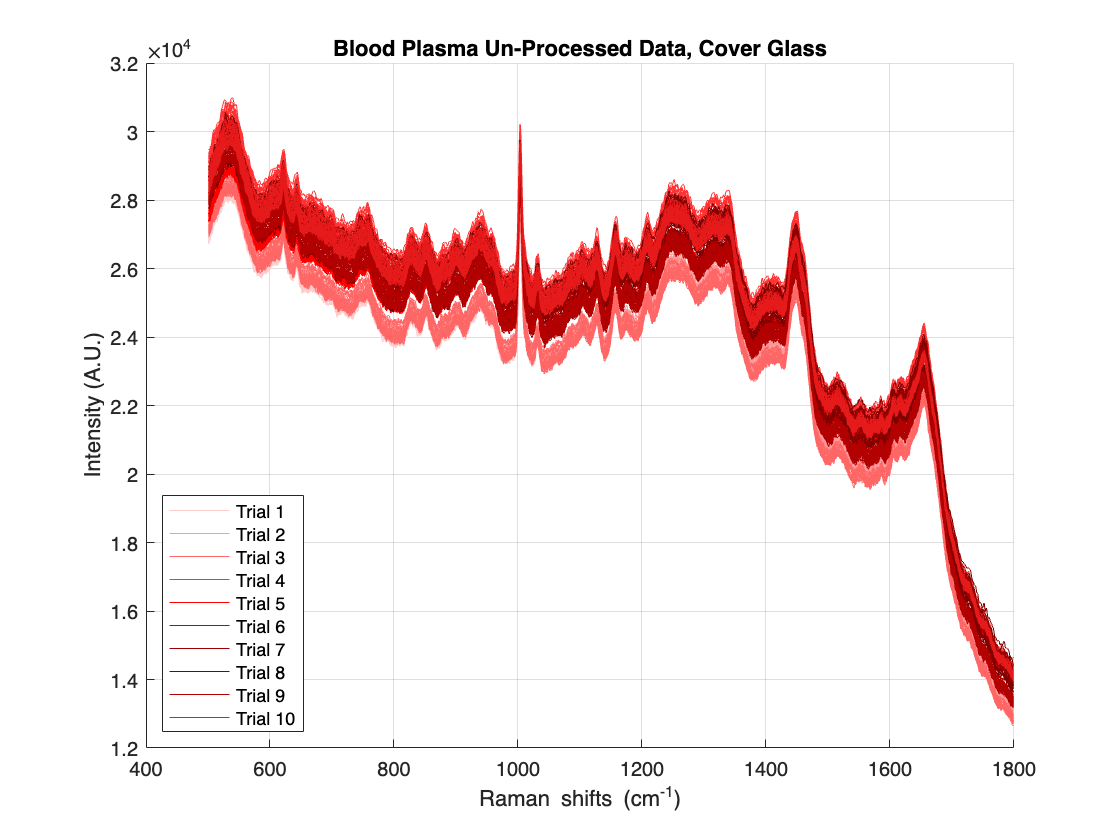

figure;
hold on;
grid on;
plot(wavenumber, blood1_A8(1,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_A8(1,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_A8(1,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_A8(1,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_A8(1,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_A8(1,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_A8(1,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_A8(1,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_A8(1,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_A8(1,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
plot(wavenumber, blood1_A8(2:end,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_A8(2:end,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_A8(2:end,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_A8(2:end,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_A8(2:end,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_A8(2:end,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_A8(2:end,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_A8(2:end,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_A8(2:end,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_A8(2:end,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9', 'Trial 10', 'location', 'southwest');
hold off;

% Preprocessing the data

pro_blood1_A8 = apply(blood1_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood2_A8 = apply(blood2_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood3_A8 = apply(blood3_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood4_A8 = apply(blood4_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood5_A8 = apply(blood5_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood6_A8 = apply(blood6_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood7_A8 = apply(blood7_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood8_A8 = apply(blood8_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood9_A8 = apply(blood9_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood10_A8 = apply(blood10_A8, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

blood_A8 = [blood1_A8;blood2_A8;blood3_A8;blood4_A8;blood5_A8;blood6_A8;blood7_A8;blood8_A8;blood9_A8;blood10_A8];
pro_blood_A8 = apply(blood_A8, [6,1,10,11,8,2,5,6,7]);

% Finding SNR

[snr, closestShift] = SNR_loc(pro_blood_A8, corr_shifts, 1003);
snr

snr =      2.951511176233870e+02


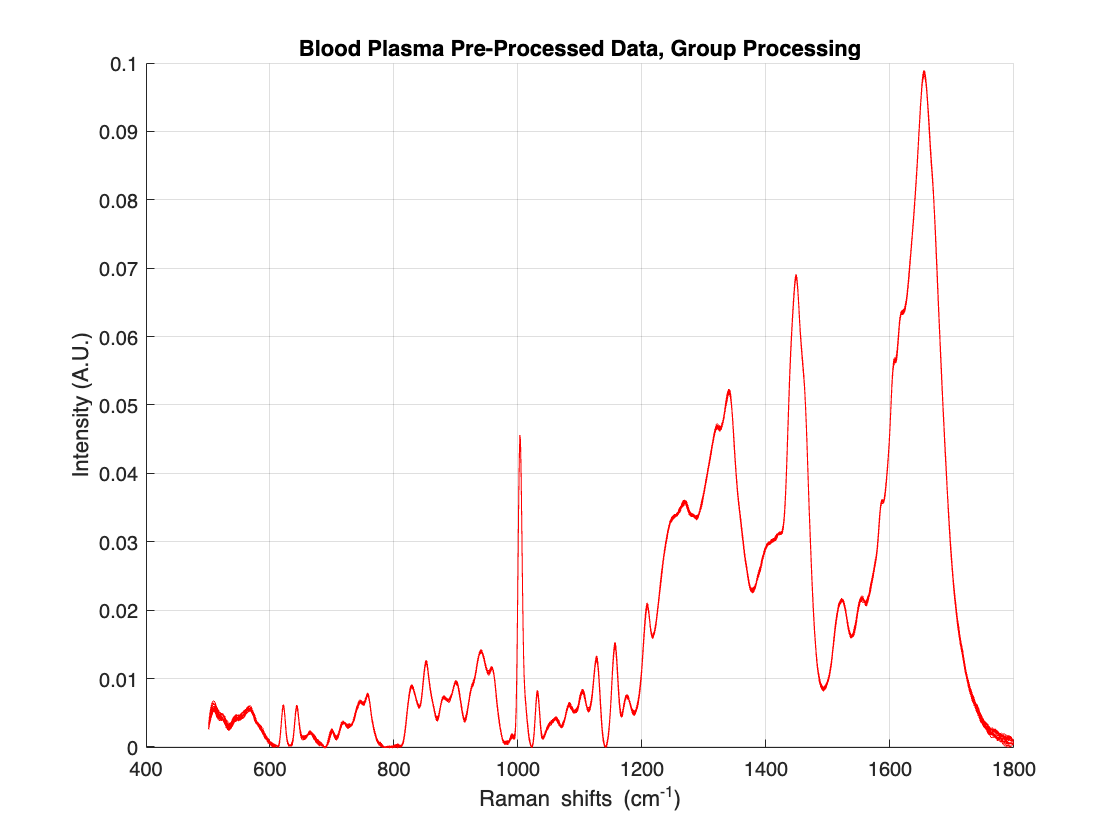

% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_blood_A8, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Group Processing');
hold off;

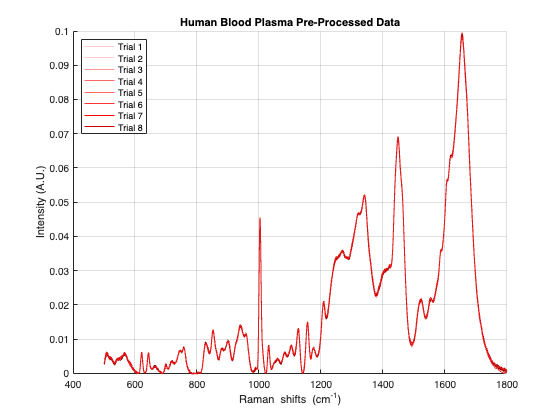

figure;
hold on;
grid on;
plot(wavenumber, pro_blood1_A8, 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, pro_blood2_A8, 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, pro_blood3_A8, 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, pro_blood4_A8, 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, pro_blood5_A8, 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, pro_blood6_A8, 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, pro_blood7_A8, 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, pro_blood8_A8, 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, pro_blood9_A8, 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, pro_blood10_A8, 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest');
hold off;

# Sample B Data

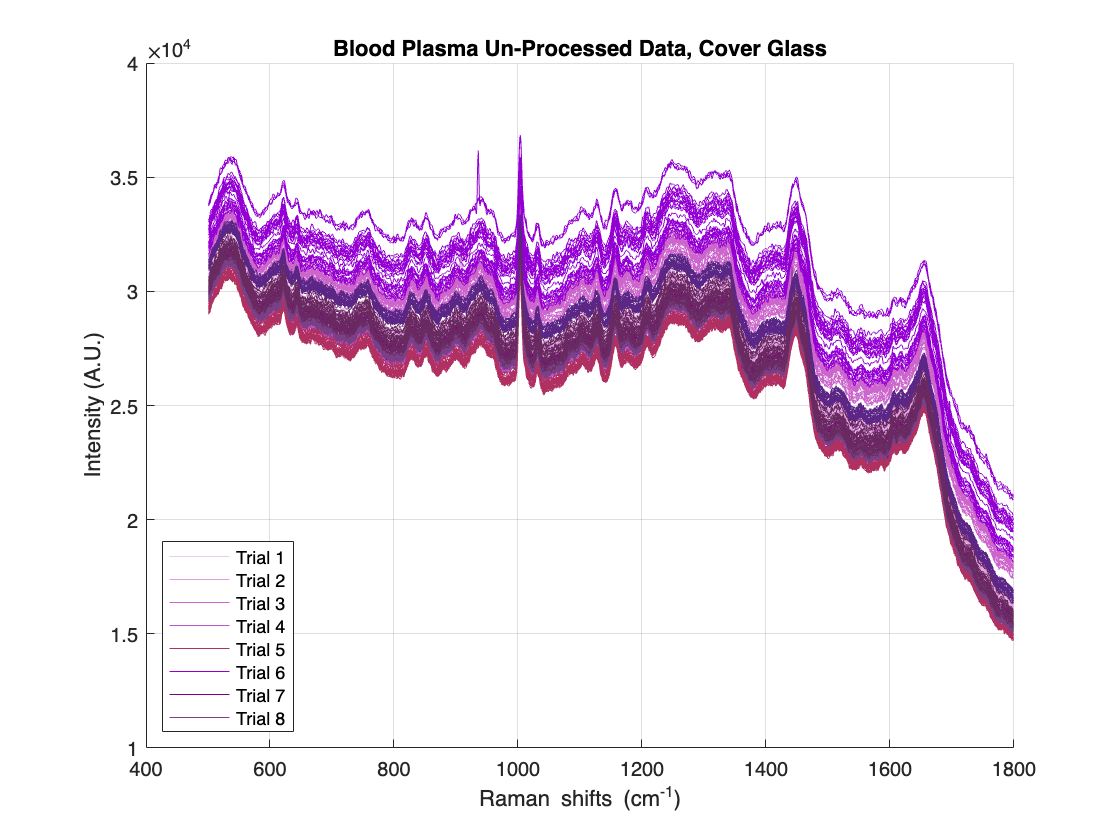

% Plotting unprocessed data

figure;
hold on;
grid on;

% Plot each trial with the specified colors
plot(wavenumber, blood1_B8(1,:), 'Color', colors(1,:));
plot(wavenumber, blood2_B8(1,:), 'Color', colors(2,:));
plot(wavenumber, blood3_B8(1,:), 'Color', colors(3,:));
plot(wavenumber, blood4_B8(1,:), 'Color', colors(4,:));
plot(wavenumber, blood5_B8(1,:), 'Color', colors(5,:));
plot(wavenumber, blood6_B8(1,:), 'Color', colors(6,:));
plot(wavenumber, blood7_B8(1,:), 'Color', colors(7,:));
plot(wavenumber, blood8_B8(1,:), 'Color', colors(8,:));
plot(wavenumber, blood9_B8(1,:), 'Color', colors(9,:));
plot(wavenumber, blood10_B8(1,:), 'Color', colors(10,:));

% Plot remaining data for each trial
plot(wavenumber, blood1_B8(2:end,:), 'Color', colors(1,:));
plot(wavenumber, blood2_B8(2:end,:), 'Color', colors(2,:));
plot(wavenumber, blood3_B8(2:end,:), 'Color', colors(3,:));
plot(wavenumber, blood4_B8(2:end,:), 'Color', colors(4,:));
plot(wavenumber, blood5_B8(2:end,:), 'Color', colors(5,:));
plot(wavenumber, blood6_B8(2:end,:), 'Color', colors(6,:));
plot(wavenumber, blood7_B8(2:end,:), 'Color', colors(7,:));
plot(wavenumber, blood8_B8(2:end,:), 'Color', colors(8,:));
plot(wavenumber, blood9_B8(2:end,:), 'Color', colors(9,:));
plot(wavenumber, blood10_B8(2:end,:), 'Color', colors(10,:));

xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8', 'Location', 'southwest');
hold off;

% Preprocessing the data

pro_blood1_B8 = apply(blood1_B8, [6,1,10,11,8,2,5,6,7]);
pro_blood2_B8 = apply(blood2_B8, [6,1,10,11,8,2,5,6,7]);
pro_blood3_B8 = apply(blood3_B8, [6,1,10,11,8,2,5,6,7]);
pro_blood4_B8 = apply(blood4_B8, [6,1,10,11,8,2,5,6,7]);
pro_blood5_B8 = apply(blood5_B8, [6,1,10,11,8,2,5,6,7]);
pro_blood6_B8 = apply(blood6_B8, [6,1,10,11,8,2,5,6,7]);
pro_blood7_B8 = apply(blood7_B8, [6,1,10,11,8,2,5,6,7]);
pro_blood8_B8 = apply(blood8_B8, [6,1,10,11,8,2,5,6,7]);
pro_blood9_B8 = apply(blood9_B8, [6,1,10,11,8,2,5,6,7]);
pro_blood10_B8 = apply(blood10_B8, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

% blood_B8 = [blood1_B8;blood2_B8;blood3_B8;blood4_B8;blood5_B8;blood6_B8;blood7_B8;blood8_B8;blood9_B8;blood10_B8];
% pro_blood_B8 = apply(blood_B8, [6,1,10,11,8,2,5,6,7]);
blood_B8 = [blood1_B8;blood2_B8;blood4_B8;blood5_B8;blood7_B8;blood8_B8;blood9_B8;blood10_B8];
pro_blood_B8 = apply(blood_B8, [6,1,10,11,8,2,5,6,7]);

blood_8 = [blood_A8;blood_B8];
pro_blood_8 = apply(blood_8, [6,1,10,11,8,2,5,6,7]);

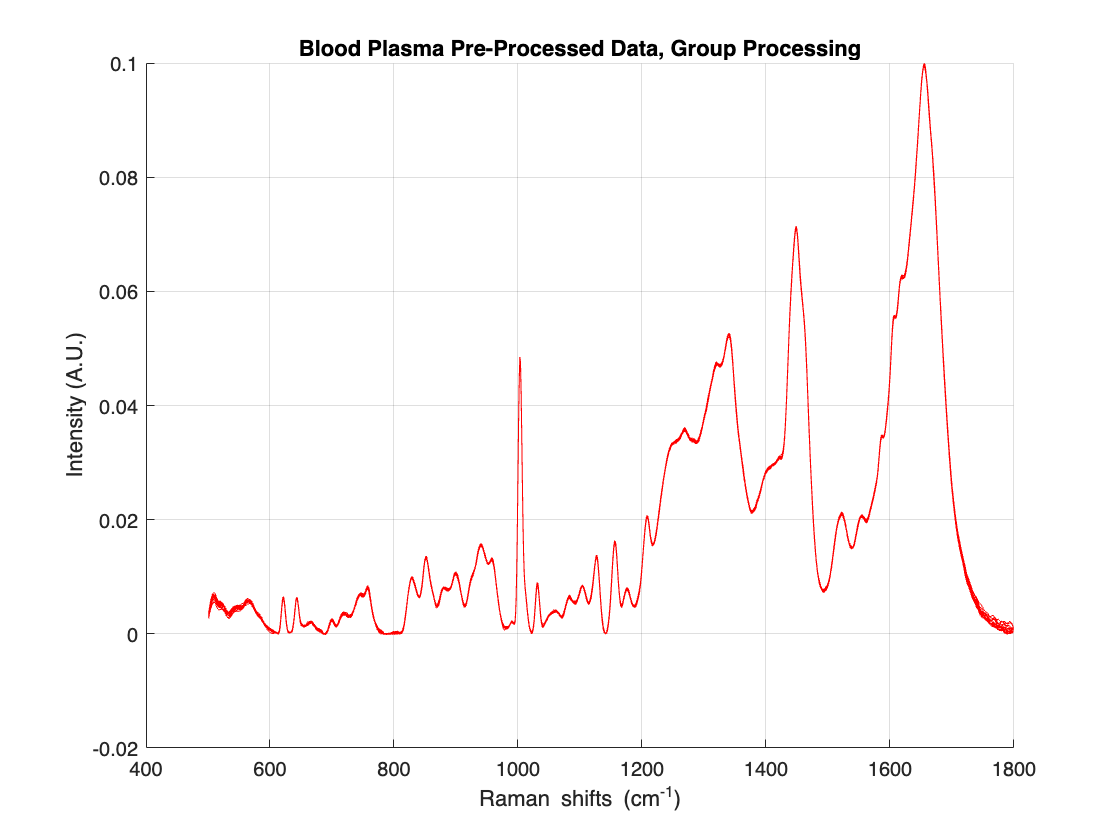

% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_blood_B8, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Group Processing');
hold off;

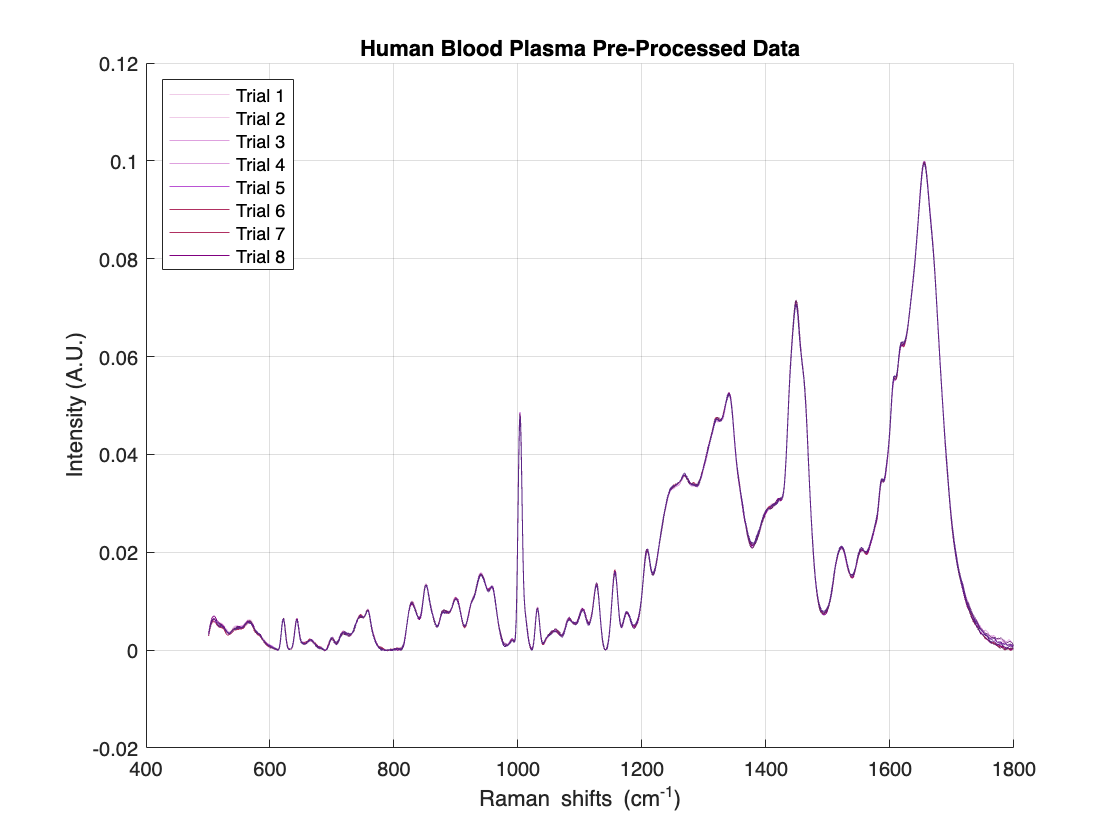

figure;
hold on;
grid on;
% Plot each trial with the specified colors
plot(wavenumber, pro_blood1_B8, 'Color', colors(1,:)); % Lavender Blush
plot(wavenumber, pro_blood2_B8, 'Color', colors(2,:)); % Thistle
%plot(wavenumber, pro_blood3_B8, 'Color', colors(3,:)); % Orchid
plot(wavenumber, pro_blood4_B8, 'Color', colors(4,:)); % Amethyst
plot(wavenumber, pro_blood5_B8, 'Color', colors(5,:)); % Plum
%plot(wavenumber, pro_blood6_B8, 'Color', colors(6,:)); % Dark Violet
plot(wavenumber, pro_blood7_B8, 'Color', colors(7,:)); % Purple
plot(wavenumber, pro_blood8_B8, 'Color', colors(8,:)); % Blue Violet
plot(wavenumber, pro_blood9_B8, 'Color', colors(9,:)); % Dark Orchid
plot(wavenumber, pro_blood10_B8, 'Color', colors(10,:)); % Indigo
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8', 'Location', 'northwest');
hold off;

# Comparison

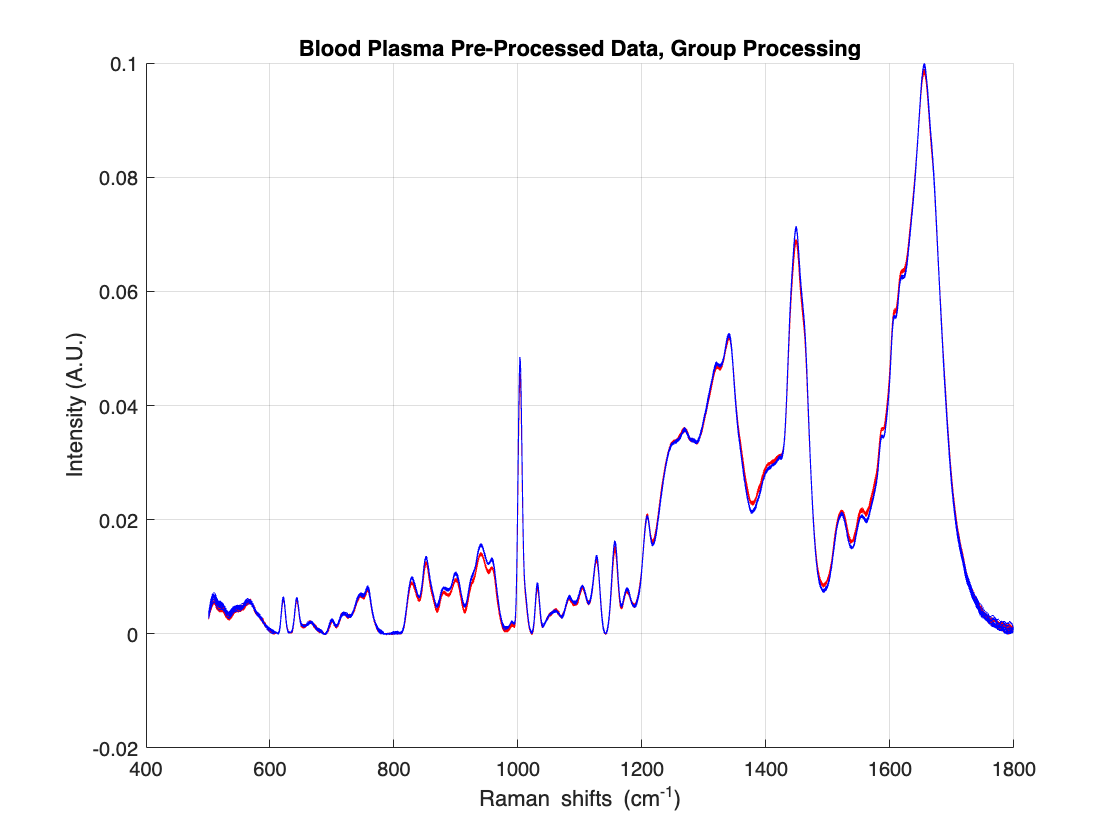

figure;
hold on;
grid on;
plot(wavenumber, pro_blood_A8, '-r');
plot(wavenumber, pro_blood_B8, '-b');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Group Processing');
hold off;

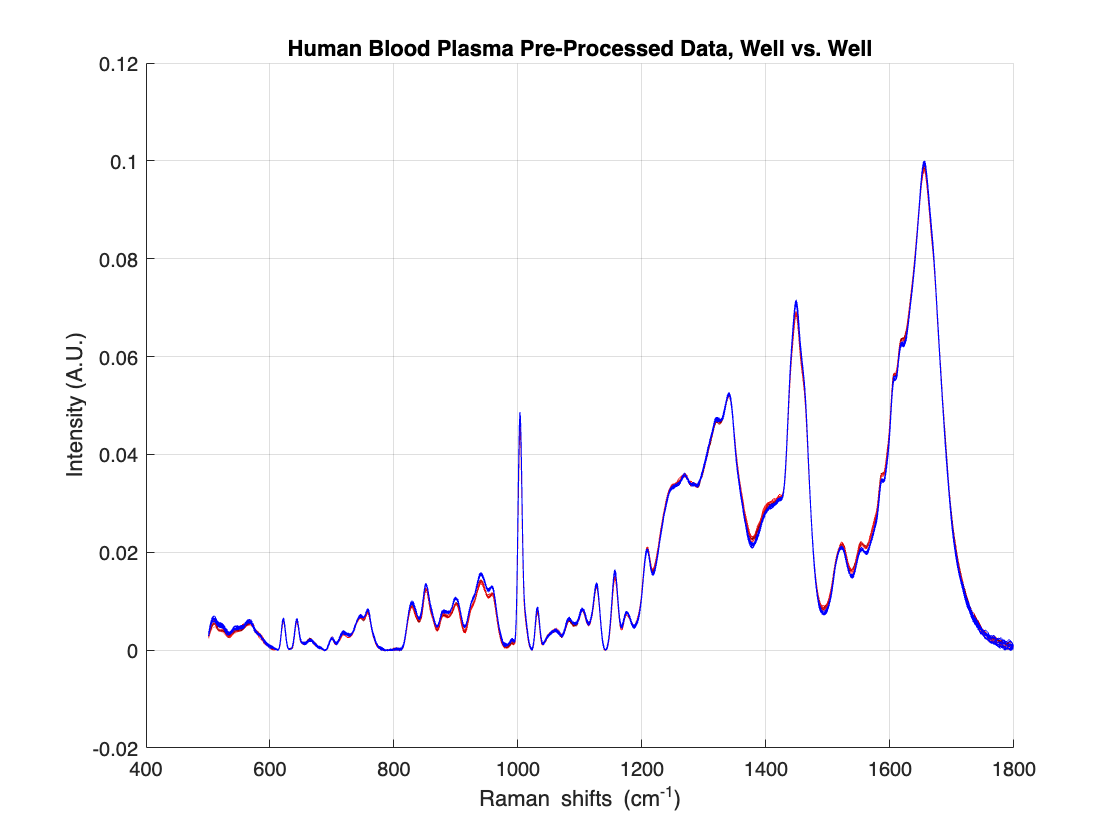

figure;
hold on;
grid on;
plot(wavenumber, pro_blood1_A8, 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, pro_blood2_A8, 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, pro_blood3_A8, 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, pro_blood4_A8, 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, pro_blood5_A8, 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, pro_blood6_A8, 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, pro_blood7_A8, 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, pro_blood8_A8, 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, pro_blood9_A8, 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, pro_blood10_A8, 'Color', [0.90, 0.10, 0.10]); % Light Red
plot(wavenumber, pro_blood1_B8, '-b');
plot(wavenumber, pro_blood2_B8, '-b');
%plot(wavenumber, pro_blood3_B8, '-b');
plot(wavenumber, pro_blood4_B8, '-b');
plot(wavenumber, pro_blood5_B8, '-b');
%plot(wavenumber, pro_blood6_B8, '-b');
plot(wavenumber, pro_blood7_B8, '-b');
plot(wavenumber, pro_blood8_B8, '-b');
plot(wavenumber, pro_blood9_B8, '-b');
plot(wavenumber, pro_blood10_B8, '-b');
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data, Well vs. Well');
hold off;

## Comparison Subplot

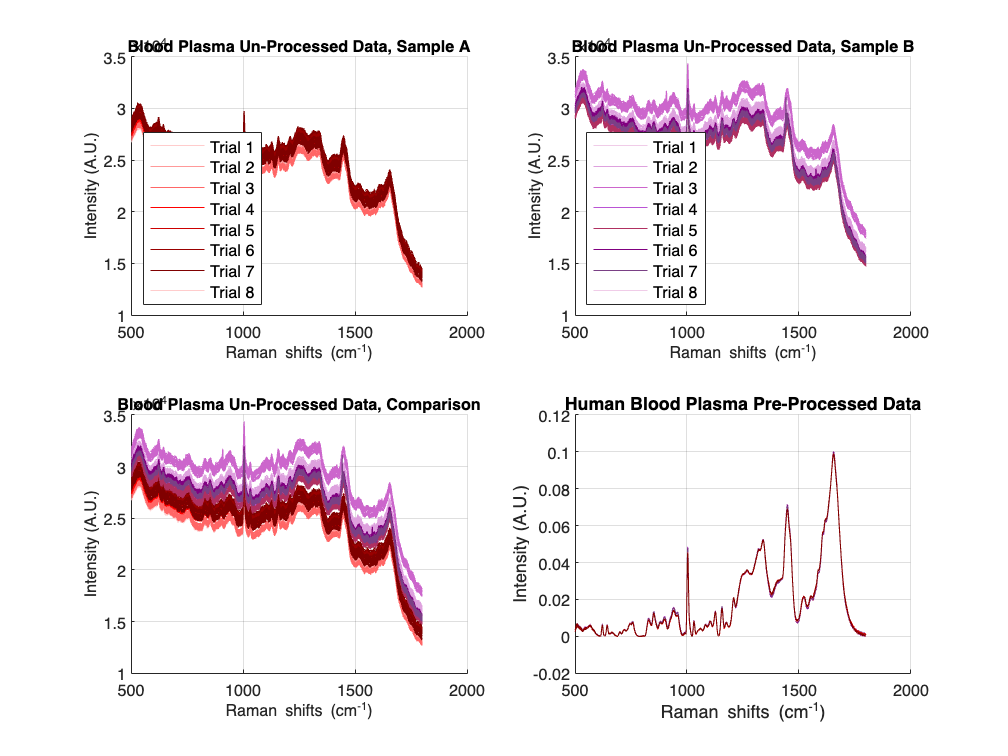

% Create a figure with subplots
figure;

% Top Left Plot
subplot(2, 2, 1);
hold on;
grid on;
fontsize(12,'points');
plot(wavenumber, blood1_A8(1,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_A8(1,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_A8(1,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
%plot(wavenumber, blood4_A8(1,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_A8(1,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_A8(1,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_A8(1,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_A8(1,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_A8(1,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood10_A8(1,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood1_A8(2:end,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_A8(2:end,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_A8(2:end,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
%plot(wavenumber, blood4_A8(2:end,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_A8(2:end,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_A8(2:end,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_A8(2:end,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_A8(2:end,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_A8(2:end,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood10_A8(2:end,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Sample A');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8', 'location', 'southwest');
hold off;

% Top Right Plot
subplot(2, 2, 2);
hold on;
grid on;
fontsize(12,'points');
plot(wavenumber, blood1_B8(1,:), 'Color', colors(1,:));
plot(wavenumber, blood2_B8(1,:), 'Color', colors(2,:));
plot(wavenumber, blood3_B8(1,:), 'Color', colors(3,:));
plot(wavenumber, blood4_B8(1,:), 'Color', colors(4,:));
plot(wavenumber, blood5_B8(1,:), 'Color', colors(5,:));
%plot(wavenumber, blood6_B8(1,:), 'Color', colors(6,:));
plot(wavenumber, blood7_B8(1,:), 'Color', colors(7,:));
plot(wavenumber, blood8_B8(1,:), 'Color', colors(8,:));
plot(wavenumber, blood9_B8(1,:), 'Color', colors(9,:));
plot(wavenumber, blood10_B8(1,:), 'Color', colors(10,:));
plot(wavenumber, blood1_B8(2:end,:), 'Color', colors(1,:));
plot(wavenumber, blood2_B8(2:end,:), 'Color', colors(2,:));
plot(wavenumber, blood3_B8(2:end,:), 'Color', colors(3,:));
plot(wavenumber, blood4_B8(2:end,:), 'Color', colors(4,:));
plot(wavenumber, blood5_B8(2:end,:), 'Color', colors(5,:));
%plot(wavenumber, blood6_B8(2:end,:), 'Color', colors(6,:));
plot(wavenumber, blood7_B8(2:end,:), 'Color', colors(7,:));
plot(wavenumber, blood8_B8(2:end,:), 'Color', colors(8,:));
plot(wavenumber, blood9_B8(2:end,:), 'Color', colors(9,:));
plot(wavenumber, blood10_B8(2:end,:), 'Color', colors(10,:));
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Sample B');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8', 'Location', 'southwest');
hold off;

% Bottom Left Plot
subplot(2, 2, 3);
hold on;
grid on;
fontsize(12,'points');
plot(wavenumber, blood1_A8(1,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_A8(1,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_A8(1,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_A8(1,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_A8(1,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_A8(1,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_A8(1,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_A8(1,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_A8(1,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood10_A8(1,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood1_A8(2:end,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_A8(2:end,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_A8(2:end,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_A8(2:end,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_A8(2:end,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_A8(2:end,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_A8(2:end,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_A8(2:end,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_A8(2:end,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood10_A8(2:end,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood1_B8(1,:), 'Color', colors(1,:));
plot(wavenumber, blood2_B8(1,:), 'Color', colors(2,:));
plot(wavenumber, blood3_B8(1,:), 'Color', colors(3,:));
plot(wavenumber, blood4_B8(1,:), 'Color', colors(4,:));
plot(wavenumber, blood5_B8(1,:), 'Color', colors(5,:));
plot(wavenumber, blood6_B8(1,:), 'Color', colors(6,:));
plot(wavenumber, blood7_B8(1,:), 'Color', colors(7,:));
plot(wavenumber, blood8_B8(1,:), 'Color', colors(8,:));
plot(wavenumber, blood9_B8(1,:), 'Color', colors(9,:));
plot(wavenumber, blood10_B8(1,:), 'Color', colors(10,:));
plot(wavenumber, blood1_B8(2:end,:), 'Color', colors(1,:));
plot(wavenumber, blood2_B8(2:end,:), 'Color', colors(2,:));
plot(wavenumber, blood3_B8(2:end,:), 'Color', colors(3,:));
plot(wavenumber, blood4_B8(2:end,:), 'Color', colors(4,:));
plot(wavenumber, blood5_B8(2:end,:), 'Color', colors(5,:));
plot(wavenumber, blood6_B8(2:end,:), 'Color', colors(6,:));
plot(wavenumber, blood7_B8(2:end,:), 'Color', colors(7,:));
plot(wavenumber, blood8_B8(2:end,:), 'Color', colors(8,:));
plot(wavenumber, blood9_B8(2:end,:), 'Color', colors(9,:));
plot(wavenumber, blood10_B8(2:end,:), 'Color', colors(10,:));
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Comparison');
hold off;

% Bottom Right Plot
subplot(2, 2, 4);
hold on;
grid on;
fontsize(9,'points');
plot(wavenumber, pro_blood1_B8, 'Color', colors(1,:)); % Lavender Blush
plot(wavenumber, pro_blood2_B8, 'Color', colors(2,:)); % Thistle
plot(wavenumber, pro_blood3_B8, 'Color', colors(3,:)); % Orchid
plot(wavenumber, pro_blood4_B8, 'Color', colors(4,:)); % Amethyst
plot(wavenumber, pro_blood5_B8, 'Color', colors(5,:)); % Plum
plot(wavenumber, pro_blood6_B8, 'Color', colors(6,:)); % Dark Violet
plot(wavenumber, pro_blood7_B8, 'Color', colors(7,:)); % Purple
plot(wavenumber, pro_blood8_B8, 'Color', colors(8,:)); % Blue Violet
plot(wavenumber, pro_blood9_B8, 'Color', colors(7,:)); % Purple
plot(wavenumber, pro_blood10_B8, 'Color', colors(8,:)); % Blue Violet
plot(wavenumber, pro_blood1_A8, 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, pro_blood2_A8, 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, pro_blood3_A8, 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, pro_blood4_A8, 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, pro_blood5_A8, 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, pro_blood6_A8, 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, pro_blood7_A8, 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, pro_blood8_A8, 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, pro_blood9_A8, 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, pro_blood10_A8, 'Color', [0.50, 0.00, 0.00]); % Maroon
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
hold off;

# Comparison vs. Collection 6 and 7

## Collection 7 Data

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-08-07/";

% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

% Sample A data

file_name = "Blood_Plasma1(40x,495mW,A)_2000_30_2024-08-07-11.32.51.930.csv";
file_path = data_path+file_name;
blood_1_A7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,A)_2000_30_2024-08-07-11.34.43.650.csv";
file_path = strcat(data_path,file_name);
blood_2_A7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,A)_2000_30_2024-08-07-11.36.14.897.csv";
file_path = strcat(data_path,file_name);
blood_3_A7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,A)_2000_30_2024-08-07-11.37.46.923.csv";
file_path = strcat(data_path,file_name);
blood_4_A7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,A)_2000_30_2024-08-07-11.39.21.133.csv";
file_path = strcat(data_path,file_name);
blood_5_A7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,A)_2000_30_2024-08-07-11.40.48.660.csv";
file_path = strcat(data_path,file_name);
blood_6_A7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,A)_2000_30_2024-08-07-11.42.15.850.csv";
file_path = strcat(data_path,file_name);
blood_7_A7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,A)_2000_30_2024-08-07-11.44.10.160.csv";
file_path = strcat(data_path,file_name);
blood_8_A7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,A)_2000_30_2024-08-07-11.45.38.440.csv";
file_path = strcat(data_path,file_name);
blood_9_A7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,A)_2000_30_2024-08-07-11.47.07.317.csv";
file_path = strcat(data_path,file_name);
blood_10_A7 = csvread(file_path, numMetadataRows, 0);

% Sample B data

file_name = "Blood_Plasma1(40x,495mW,B)_2000_30_2024-08-07-12.07.48.253.csv";
file_path = data_path+file_name;
blood_1_B7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,B)_2000_30_2024-08-07-12.09.33.347.csv";
file_path = strcat(data_path,file_name);
blood_2_B7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,B)_2000_30_2024-08-07-12.10.58.447.csv";
file_path = strcat(data_path,file_name);
blood_3_B7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,B)_2000_30_2024-08-07-12.12.25.997.csv";
file_path = strcat(data_path,file_name);
blood_4_B7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,B)_2000_30_2024-08-07-12.13.54.397.csv";
file_path = strcat(data_path,file_name);
blood_5_B7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,B)_2000_30_2024-08-07-12.15.19.350.csv";
file_path = strcat(data_path,file_name);
blood_6_B7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,B)_2000_30_2024-08-07-12.16.45.803.csv";
file_path = strcat(data_path,file_name);
blood_7_B7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,B)_2000_30_2024-08-07-12.18.15.630.csv";
file_path = strcat(data_path,file_name);
blood_8_B7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,B)_2000_30_2024-08-07-12.19.49.527.csv";
file_path = strcat(data_path,file_name);
blood_9_B7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,B)_2000_30_2024-08-07-12.21.17.850.csv";
file_path = strcat(data_path,file_name);
blood_10_B7 = csvread(file_path, numMetadataRows, 0);

file_name = "NIST(40x,495mW)_50_250_2024-08-07-11.05.42.413.csv";
file_path = strcat(data_path,file_name);
NISTspectrum = csvread(file_path, numMetadataRows, 0);

file_name = "Polystyrene(40x,495mW)_60_250_2024-08-07-11.00.37.477.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_50_250_2024-08-07-10.57.09.250.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1_A7(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;

wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];

blood_1_A7(:, blood_1_A7(1, :) <= t1) = [];
blood_1_A7(:, blood_1_A7(1, :) >= t2) = [];
blood_2_A7(:, blood_2_A7(1, :) <= t1) = [];
blood_2_A7(:, blood_2_A7(1, :) >= t2) = [];
blood_3_A7(:, blood_3_A7(1, :) <= t1) = [];
blood_3_A7(:, blood_3_A7(1, :) >= t2) = [];
blood_4_A7(:, blood_4_A7(1, :) <= t1) = [];
blood_4_A7(:, blood_4_A7(1, :) >= t2) = [];
blood_5_A7(:, blood_5_A7(1, :) <= t1) = [];
blood_5_A7(:, blood_5_A7(1, :) >= t2) = [];
blood_6_A7(:, blood_6_A7(1, :) <= t1) = [];
blood_6_A7(:, blood_6_A7(1, :) >= t2) = [];
blood_7_A7(:, blood_7_A7(1, :) <= t1) = [];
blood_7_A7(:, blood_7_A7(1, :) >= t2) = [];
blood_8_A7(:, blood_8_A7(1, :) <= t1) = [];
blood_8_A7(:, blood_8_A7(1, :) >= t2) = [];
blood_9_A7(:, blood_9_A7(1, :) <= t1) = [];
blood_9_A7(:, blood_9_A7(1, :) >= t2) = [];
blood_10_A7(:, blood_10_A7(1, :) <= t1) = [];
blood_10_A7(:, blood_10_A7(1, :) >= t2) = [];

blood_1_B7(:, blood_1_B7(1, :) <= t1) = [];
blood_1_B7(:, blood_1_B7(1, :) >= t2) = [];
blood_2_B7(:, blood_2_B7(1, :) <= t1) = [];
blood_2_B7(:, blood_2_B7(1, :) >= t2) = [];
blood_3_B7(:, blood_3_B7(1, :) <= t1) = [];
blood_3_B7(:, blood_3_B7(1, :) >= t2) = [];
blood_4_B7(:, blood_4_B7(1, :) <= t1) = [];
blood_4_B7(:, blood_4_B7(1, :) >= t2) = [];
blood_5_B7(:, blood_5_B7(1, :) <= t1) = [];
blood_5_B7(:, blood_5_B7(1, :) >= t2) = [];
blood_6_B7(:, blood_6_B7(1, :) <= t1) = [];
blood_6_B7(:, blood_6_B7(1, :) >= t2) = [];
blood_7_B7(:, blood_7_B7(1, :) <= t1) = [];
blood_7_B7(:, blood_7_B7(1, :) >= t2) = [];
blood_8_B7(:, blood_8_B7(1, :) <= t1) = [];
blood_8_B7(:, blood_8_B7(1, :) >= t2) = [];
blood_9_B7(:, blood_9_B7(1, :) <= t1) = [];
blood_9_B7(:, blood_9_B7(1, :) >= t2) = [];
blood_10_B7(:, blood_10_B7(1, :) <= t1) = [];
blood_10_B7(:, blood_10_B7(1, :) >= t2) = [];


shifts = wavenumber;

blood1_A7 = blood_1_A7(2:end, :);
blood2_A7 = blood_2_A7(2:end, :);
blood3_A7 = blood_3_A7(2:end, :);
blood4_A7 = blood_4_A7(2:end, :);
blood5_A7 = blood_5_A7(2:end, :);
blood6_A7 = blood_6_A7(2:end, :);
blood7_A7 = blood_7_A7(2:end, :);
blood8_A7 = blood_8_A7(2:end, :);
blood9_A7 = blood_9_A7(2:end, :);
blood10_A7 = blood_10_A7(2:end, :);

blood1_B7 = blood_1_B7(2:end, :);
blood2_B7 = blood_2_B7(2:end, :);
blood3_B7 = blood_3_B7(2:end, :);
blood4_B7 = blood_4_B7(2:end, :);
blood5_B7 = blood_5_B7(2:end, :);
blood6_B7 = blood_6_B7(2:end, :);
blood7_B7 = blood_7_B7(2:end, :);
blood8_B7 = blood_8_B7(2:end, :);
blood9_B7 = blood_9_B7(2:end, :);
blood10_B7 = blood_10_B7(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

% Checking for processing full dataset at once vs individual

% blood_A7 = [blood1_A7;blood2_A7;blood3_A7;blood4_A7;blood5_A7;blood6_A7;blood7_A7;blood8_A7;blood9_A7;blood10_A7];
% pro_blood_A7 = apply(blood_A7, [6,1,10,11,8,2,5,6,7]);

blood_A7 = [blood1_A7;blood2_A7;blood3_A7;blood4_A7;blood5_A7;blood6_A7;blood7_A7;blood8_A7];
pro_blood_A7 = apply(blood_A7, [6,1,10,11,8,2,5,6,7]);

% blood_B7 = [blood1_B7;blood2_B7;blood3_B7;blood4_B7;blood5_B7;blood6_B7;blood7_B7;blood8_B7;blood9_B7;blood10_B7];
% pro_blood_B7 = apply(blood_B7, [6,1,10,11,8,2,5,6,7]);

blood_B7 = [blood1_B7;blood2_B7;blood3_B7;blood4_B7;blood5_B7;blood6_B7;blood7_B7;blood8_B7];
pro_blood_B7 = apply(blood_B7, [6,1,10,11,8,2,5,6,7]);

blood_7 = [blood_A7;blood_B7];
pro_blood_7 = apply(blood_7, [6,1,10,11,8,2,5,6,7]);

## Collection 6 Data

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-08-06/";

% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

% Sample A data

file_name = "Blood_Plasma1(40x,495mW,A)_2000_30_2024-08-06-11.51.33.447.csv";
file_path = data_path+file_name;
blood_1_A6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,A)_2000_30_2024-08-06-11.53.03.510.csv";
file_path = strcat(data_path,file_name);
blood_2_A6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,A)_2000_30_2024-08-06-11.54.31.647.csv";
file_path = strcat(data_path,file_name);
blood_3_A6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,A)_2000_30_2024-08-06-11.55.57.317.csv";
file_path = strcat(data_path,file_name);
blood_4_A6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,A)_2000_30_2024-08-06-11.57.23.833.csv";
file_path = strcat(data_path,file_name);
blood_5_A6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,A)_2000_30_2024-08-06-11.58.50.513.csv";
file_path = strcat(data_path,file_name);
blood_6_A6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,A)_2000_30_2024-08-06-12.00.15.227.csv";
file_path = strcat(data_path,file_name);
blood_7_A6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,A)_2000_30_2024-08-06-12.01.42.983.csv";
file_path = strcat(data_path,file_name);
blood_8_A6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,A)_2000_30_2024-08-06-12.03.07.357.csv";
file_path = strcat(data_path,file_name);
blood_9_A6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,A)_2000_30_2024-08-06-12.04.36.800.csv";
file_path = strcat(data_path,file_name);
blood_10_A6 = csvread(file_path, numMetadataRows, 0);

% Sample B data

file_name = "Blood_Plasma1(40x,495mW,B)_2000_30_2024-08-06-12.25.11.263.csv";
file_path = data_path+file_name;
blood_1_B6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,B)_2000_30_2024-08-06-12.26.43.953.csv";
file_path = strcat(data_path,file_name);
blood_2_B6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,B)_2000_30_2024-08-06-12.28.14.497.csv";
file_path = strcat(data_path,file_name);
blood_3_B6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,B)_2000_30_2024-08-06-12.29.38.903.csv";
file_path = strcat(data_path,file_name);
blood_4_B6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,B)_2000_30_2024-08-06-12.31.03.950.csv";
file_path = strcat(data_path,file_name);
blood_5_B6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,B)_2000_30_2024-08-06-12.32.31.723.csv";
file_path = strcat(data_path,file_name);
blood_6_B6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,B)_2000_30_2024-08-06-12.34.01.010.csv";
file_path = strcat(data_path,file_name);
blood_7_B6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,B)_2000_30_2024-08-06-12.35.25.610.csv";
file_path = strcat(data_path,file_name);
blood_8_B6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,B)_2000_30_2024-08-06-12.36.52.950.csv";
file_path = strcat(data_path,file_name);
blood_9_B6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,B)_2000_30_2024-08-06-12.38.17.393.csv";
file_path = strcat(data_path,file_name);
blood_10_B6 = csvread(file_path, numMetadataRows, 0);

file_name = "NIST(40x,495mW)_50_250_2024-08-06-11.22.53.540.csv";
file_path = strcat(data_path,file_name);
NISTspectrum = csvread(file_path, numMetadataRows, 0);

file_name = "Polystyrene(40x,495mW)_60_250_2024-08-06-11.18.22.663.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_50_250_2024-08-06-11.14.46.743.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1_A6(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;

wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];

blood_1_A6(:, blood_1_A6(1, :) <= t1) = [];
blood_1_A6(:, blood_1_A6(1, :) >= t2) = [];
blood_2_A6(:, blood_2_A6(1, :) <= t1) = [];
blood_2_A6(:, blood_2_A6(1, :) >= t2) = [];
blood_3_A6(:, blood_3_A6(1, :) <= t1) = [];
blood_3_A6(:, blood_3_A6(1, :) >= t2) = [];
blood_4_A6(:, blood_4_A6(1, :) <= t1) = [];
blood_4_A6(:, blood_4_A6(1, :) >= t2) = [];
blood_5_A6(:, blood_5_A6(1, :) <= t1) = [];
blood_5_A6(:, blood_5_A6(1, :) >= t2) = [];
blood_6_A6(:, blood_6_A6(1, :) <= t1) = [];
blood_6_A6(:, blood_6_A6(1, :) >= t2) = [];
blood_7_A6(:, blood_7_A6(1, :) <= t1) = [];
blood_7_A6(:, blood_7_A6(1, :) >= t2) = [];
blood_8_A6(:, blood_8_A6(1, :) <= t1) = [];
blood_8_A6(:, blood_8_A6(1, :) >= t2) = [];
blood_9_A6(:, blood_9_A6(1, :) <= t1) = [];
blood_9_A6(:, blood_9_A6(1, :) >= t2) = [];
blood_10_A6(:, blood_10_A6(1, :) <= t1) = [];
blood_10_A6(:, blood_10_A6(1, :) >= t2) = [];

blood_1_B6(:, blood_1_B6(1, :) <= t1) = [];
blood_1_B6(:, blood_1_B6(1, :) >= t2) = [];
blood_2_B6(:, blood_2_B6(1, :) <= t1) = [];
blood_2_B6(:, blood_2_B6(1, :) >= t2) = [];
blood_3_B6(:, blood_3_B6(1, :) <= t1) = [];
blood_3_B6(:, blood_3_B6(1, :) >= t2) = [];
blood_4_B6(:, blood_4_B6(1, :) <= t1) = [];
blood_4_B6(:, blood_4_B6(1, :) >= t2) = [];
blood_5_B6(:, blood_5_B6(1, :) <= t1) = [];
blood_5_B6(:, blood_5_B6(1, :) >= t2) = [];
blood_6_B6(:, blood_6_B6(1, :) <= t1) = [];
blood_6_B6(:, blood_6_B6(1, :) >= t2) = [];
blood_7_B6(:, blood_7_B6(1, :) <= t1) = [];
blood_7_B6(:, blood_7_B6(1, :) >= t2) = [];
blood_8_B6(:, blood_8_B6(1, :) <= t1) = [];
blood_8_B6(:, blood_8_B6(1, :) >= t2) = [];
blood_9_B6(:, blood_9_B6(1, :) <= t1) = [];
blood_9_B6(:, blood_9_B6(1, :) >= t2) = [];
blood_10_B6(:, blood_10_B6(1, :) <= t1) = [];
blood_10_B6(:, blood_10_B6(1, :) >= t2) = [];


shifts = wavenumber;

blood1_A6 = blood_1_A6(2:end, :);
blood2_A6 = blood_2_A6(2:end, :);
blood3_A6 = blood_3_A6(2:end, :);
blood4_A6 = blood_4_A6(2:end, :);
blood5_A6 = blood_5_A6(2:end, :);
blood6_A6 = blood_6_A6(2:end, :);
blood7_A6 = blood_7_A6(2:end, :);
blood8_A6 = blood_8_A6(2:end, :);
blood9_A6 = blood_9_A6(2:end, :);
blood10_A6 = blood_10_A6(2:end, :);

blood1_B6 = blood_1_B6(2:end, :);
blood2_B6 = blood_2_B6(2:end, :);
blood3_B6 = blood_3_B6(2:end, :);
blood4_B6 = blood_4_B6(2:end, :);
blood5_B6 = blood_5_B6(2:end, :);
blood6_B6 = blood_6_B6(2:end, :);
blood7_B6 = blood_7_B6(2:end, :);
blood8_B6 = blood_8_B6(2:end, :);
blood9_B6 = blood_9_B6(2:end, :);
blood10_B6 = blood_10_B6(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

% Checking for processing full dataset at once vs individual

% blood_A6 = [blood1_A6;blood2_A6;blood3_A6;blood4_A6;blood5_A6;blood6_A6;blood7_A6;blood8_A6;blood9_A6;blood10_A6];
% pro_blood_A6 = apply(blood_A6, [6,1,10,11,8,2,5,6,7]);

blood_A6 = [blood1_A6;blood2_A6;blood3_A6;blood4_A6;blood5_A6;blood6_A6;blood7_A6;blood8_A6];
pro_blood_A6 = apply(blood_A6, [6,1,10,11,8,2,5,6,7]);

% blood_B6 = [blood1_B6;blood2_B6;blood3_B6;blood4_B6;blood5_B6;blood6_B6;blood7_B6;blood8_B6;blood9_B6;blood10_B6];
% pro_blood_B6 = apply(blood_B6, [6,1,10,11,8,2,5,6,7]);

blood_B6 = [blood1_B6;blood2_B6;blood3_B6;blood4_B6;blood5_B6;blood6_B6;blood7_B6;blood8_B6];
pro_blood_B6 = apply(blood_B6, [6,1,10,11,8,2,5,6,7]);

blood_6 = [blood_A6;blood_B6];
pro_blood_6 = apply(blood_6, [6,1,10,11,8,2,5,6,7]);

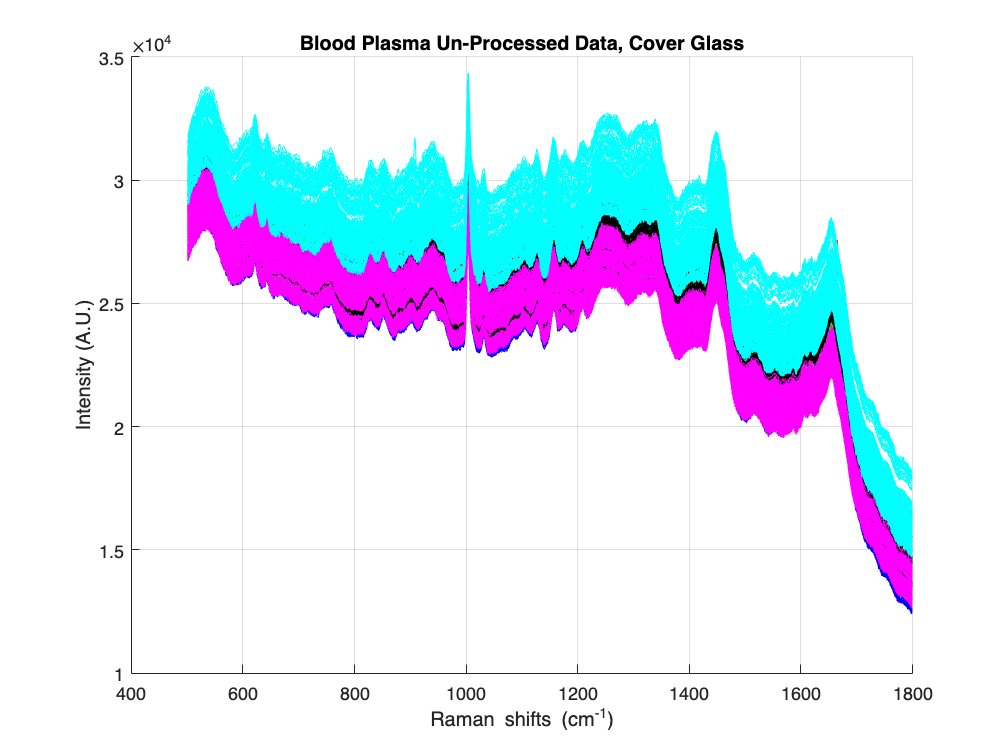

% Plotting unprocessed data

figure;
hold on;
grid on;
plot(wavenumber, blood1_A6, '-r');
plot(wavenumber, blood2_A6, '-r');
plot(wavenumber, blood3_A6, '-r');
plot(wavenumber, blood4_A6, '-r');
plot(wavenumber, blood5_A6, '-r');
plot(wavenumber, blood6_A6, '-r');
plot(wavenumber, blood7_A6, '-r');
plot(wavenumber, blood8_A6, '-r');
% plot(wavenumber, blood9_A6, '-r');
% plot(wavenumber, blood10_A6, '-r');
plot(wavenumber, blood1_A7, '-b');
plot(wavenumber, blood2_A7, '-b');
plot(wavenumber, blood3_A7, '-b');
plot(wavenumber, blood4_A7, '-b');
plot(wavenumber, blood5_A7, '-b');
plot(wavenumber, blood6_A7, '-b');
plot(wavenumber, blood7_A7, '-b');
plot(wavenumber, blood8_A7, '-b');
% plot(wavenumber, blood9_A7, '-b');
% plot(wavenumber, blood10_A7, '-b');
plot(wavenumber, blood1_B7, '-g');
plot(wavenumber, blood2_B7, '-g');
plot(wavenumber, blood3_B7, '-g');
plot(wavenumber, blood4_B7, '-g');
plot(wavenumber, blood5_B7, '-g');
plot(wavenumber, blood6_B7, '-g');
plot(wavenumber, blood7_B7, '-g');
plot(wavenumber, blood8_B7, '-g');
% plot(wavenumber, blood9_B7, '-g');
% plot(wavenumber, blood10_B7, '-g');
plot(wavenumber, blood1_B6, '-k');
plot(wavenumber, blood2_B6, '-k');
plot(wavenumber, blood3_B6, '-k');
plot(wavenumber, blood4_B6, '-k');
plot(wavenumber, blood5_B6, '-k');
plot(wavenumber, blood6_B6, '-k');
plot(wavenumber, blood7_B6, '-k');
plot(wavenumber, blood8_B6, '-k');
% plot(wavenumber, blood9_B6, '-k');
% plot(wavenumber, blood10_B6, '-k');
plot(wavenumber, blood1_A8, '-m');
plot(wavenumber, blood2_A8, '-m');
plot(wavenumber, blood3_A8, '-m');
plot(wavenumber, blood4_A8, '-m');
plot(wavenumber, blood5_A8, '-m');
plot(wavenumber, blood6_A8, '-m');
plot(wavenumber, blood7_A8, '-m');
plot(wavenumber, blood8_A8, '-m');
plot(wavenumber, blood9_A8, '-m');
plot(wavenumber, blood10_A8, '-m');
plot(wavenumber, blood1_B8, '-c');
plot(wavenumber, blood2_B8, '-c');
%plot(wavenumber, blood3_B8, '-c');
plot(wavenumber, blood4_B8, '-c');
plot(wavenumber, blood5_B8, '-c');
%plot(wavenumber, blood6_B8, '-c');
plot(wavenumber, blood7_B8, '-c');
plot(wavenumber, blood8_B8, '-c');
plot(wavenumber, blood9_B8, '-c');
plot(wavenumber, blood10_B8, '-c');
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
hold off;

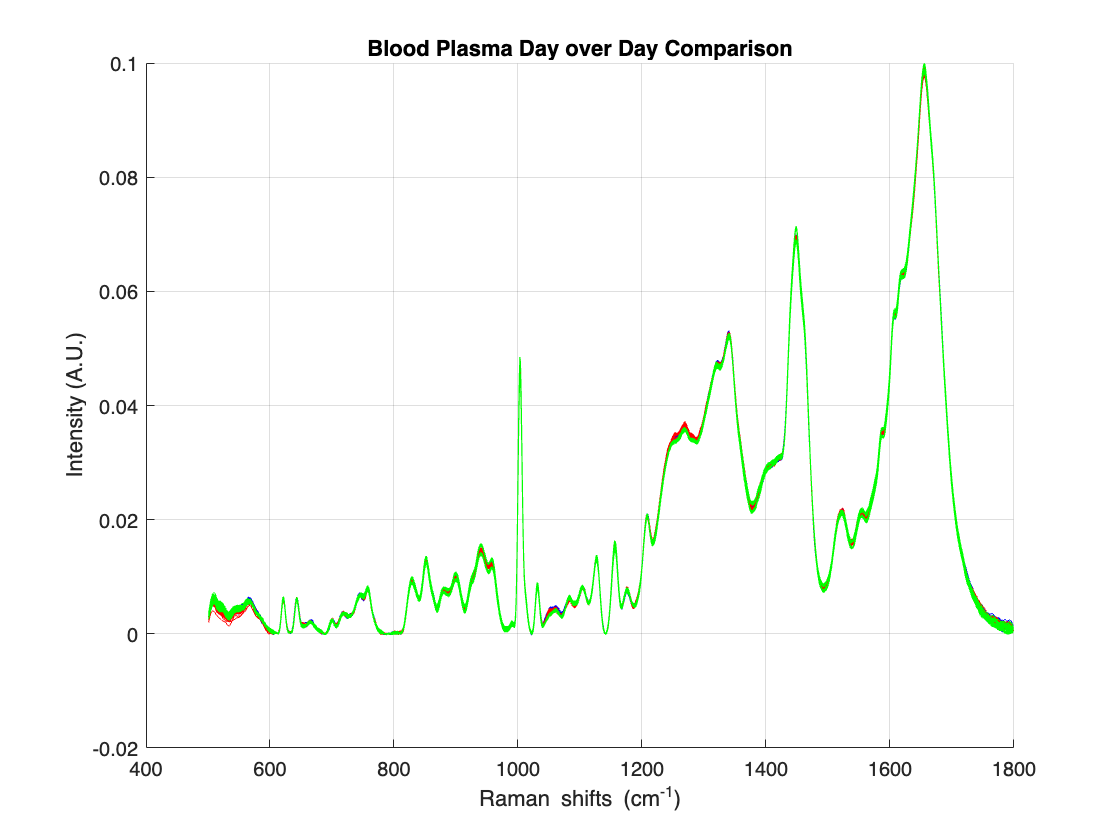

% Plotting processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_blood_A7, '-b');
plot(wavenumber, pro_blood_B7, '-b');
plot(wavenumber, pro_blood_A6, '-r');
plot(wavenumber, pro_blood_B6, '-r');
plot(wavenumber, pro_blood_A8, '-g');
plot(wavenumber, pro_blood_B8, '-g');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Day over Day Comparison');
hold off;

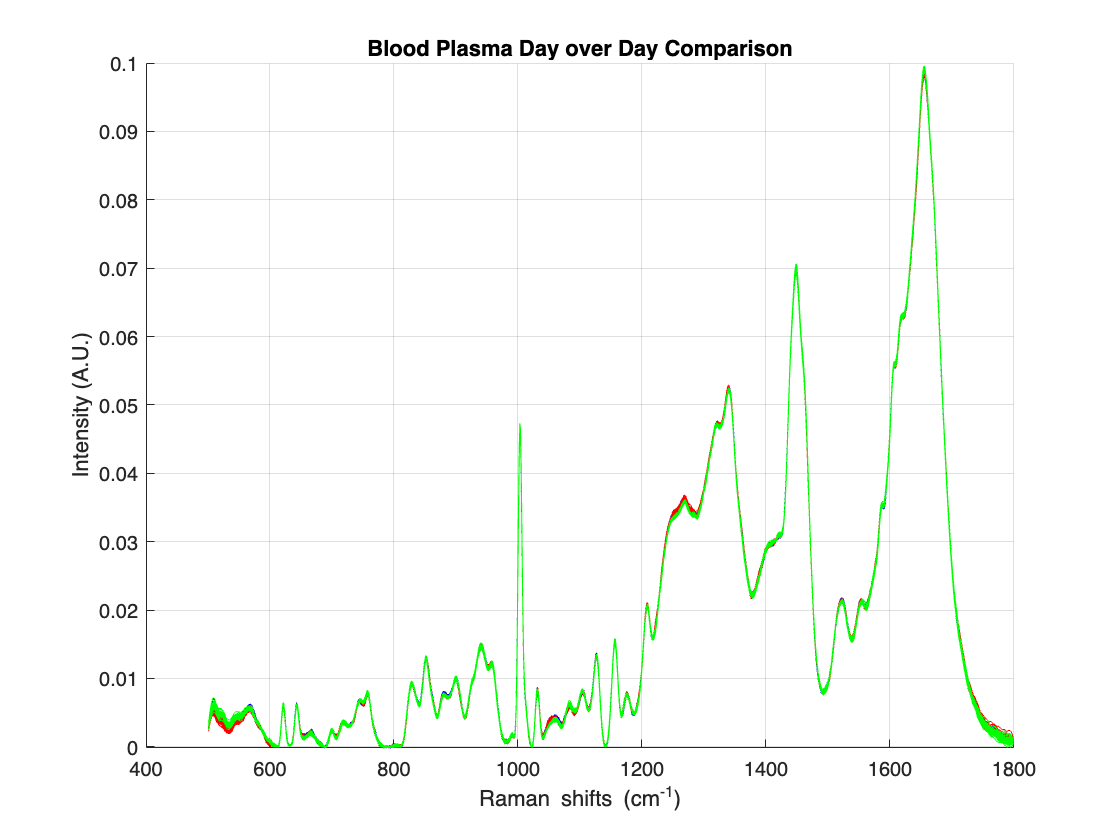

% Plotting day-grouping processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_blood_7, '-b');
plot(wavenumber, pro_blood_6, '-r');
plot(wavenumber, pro_blood_8, '-g');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Day over Day Comparison');
hold off;

% T-tests for the 1003cm-1 peak

Trial1 = pro_blood_A7(:,503);
Trial2 = pro_blood_B7(:,503);
Trial3 = pro_blood_A6(:,503);
Trial4 = pro_blood_B6(:,503);
Trial5 = pro_blood_A8(:,503); % New trial A8
Trial6 = pro_blood_B8(:,503); % New trial B8

% Calculate means
av_Trial1 = mean(Trial1);
av_Trial2 = mean(Trial2);
av_Trial3 = mean(Trial3);
av_Trial4 = mean(Trial4);
av_Trial5 = mean(Trial5); % New trial A8
av_Trial6 = mean(Trial6); % New trial B8

% Calculate standard deviations
std_Trial1 = std(Trial1);
std_Trial2 = std(Trial2);
std_Trial3 = std(Trial3);
std_Trial4 = std(Trial4);
std_Trial5 = std(Trial5); % New trial A8
std_Trial6 = std(Trial6); % New trial B8

% Number of spectra in each collection
n_Trial1 = size(Trial1, 1);
n_Trial2 = size(Trial2, 1);
n_Trial3 = size(Trial3, 1);
n_Trial4 = size(Trial4, 1);
n_Trial5 = size(Trial5, 1); % New trial A8
n_Trial6 = size(Trial6, 1); % New trial B8

% Perform t-tests between pairs
[t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2] = perform_ttest(av_Trial1, av_Trial2, std_Trial1, std_Trial2, n_Trial1, n_Trial2);
[t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3] = perform_ttest(av_Trial1, av_Trial3, std_Trial1, std_Trial3, n_Trial1, n_Trial3);
[t_Trial1_Trial4, p_Trial1_Trial4, df_Trial1_Trial4] = perform_ttest(av_Trial1, av_Trial4, std_Trial1, std_Trial4, n_Trial1, n_Trial4);
[t_Trial1_Trial5, p_Trial1_Trial5, df_Trial1_Trial5] = perform_ttest(av_Trial1, av_Trial5, std_Trial1, std_Trial5, n_Trial1, n_Trial5); % New pair
[t_Trial1_Trial6, p_Trial1_Trial6, df_Trial1_Trial6] = perform_ttest(av_Trial1, av_Trial6, std_Trial1, std_Trial6, n_Trial1, n_Trial6); % New pair

[t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3] = perform_ttest(av_Trial2, av_Trial3, std_Trial2, std_Trial3, n_Trial2, n_Trial3);
[t_Trial2_Trial4, p_Trial2_Trial4, df_Trial2_Trial4] = perform_ttest(av_Trial2, av_Trial4, std_Trial2, std_Trial4, n_Trial2, n_Trial4);
[t_Trial2_Trial5, p_Trial2_Trial5, df_Trial2_Trial5] = perform_ttest(av_Trial2, av_Trial5, std_Trial2, std_Trial5, n_Trial2, n_Trial5); % New pair
[t_Trial2_Trial6, p_Trial2_Trial6, df_Trial2_Trial6] = perform_ttest(av_Trial2, av_Trial6, std_Trial2, std_Trial6, n_Trial2, n_Trial6); % New pair

[t_Trial3_Trial4, p_Trial3_Trial4, df_Trial3_Trial4] = perform_ttest(av_Trial3, av_Trial4, std_Trial3, std_Trial4, n_Trial3, n_Trial4);
[t_Trial3_Trial5, p_Trial3_Trial5, df_Trial3_Trial5] = perform_ttest(av_Trial3, av_Trial5, std_Trial3, std_Trial5, n_Trial3, n_Trial5); % New pair
[t_Trial3_Trial6, p_Trial3_Trial6, df_Trial3_Trial6] = perform_ttest(av_Trial3, av_Trial6, std_Trial3, std_Trial6, n_Trial3, n_Trial6); % New pair

[t_Trial4_Trial5, p_Trial4_Trial5, df_Trial4_Trial5] = perform_ttest(av_Trial4, av_Trial5, std_Trial4, std_Trial5, n_Trial4, n_Trial5); % New pair
[t_Trial4_Trial6, p_Trial4_Trial6, df_Trial4_Trial6] = perform_ttest(av_Trial4, av_Trial6, std_Trial4, std_Trial6, n_Trial4, n_Trial6); % New pair

[t_Trial5_Trial6, p_Trial5_Trial6, df_Trial5_Trial6] = perform_ttest(av_Trial5, av_Trial6, std_Trial5, std_Trial6, n_Trial5, n_Trial6); % New pair

% Display results
fprintf('t-test and p values for pairwise comparisons at 1003cm^-1 peak:\n');

t-test and p values for pairwise comparisons at 1003cm^-1 peak:


fprintf('Trial 1 vs Trial 2: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2);

Trial 1 vs Trial 2: t = 1.4630, p = 0.1554, df = 26.0192


fprintf('Trial 1 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3);

Trial 1 vs Trial 3: t = 7.5762, p = 0.0000, df = 26.9594


fprintf('Trial 1 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial4, p_Trial1_Trial4, df_Trial1_Trial4);

Trial 1 vs Trial 4: t = 0.3514, p = 0.7281, df = 26.7265


fprintf('Trial 1 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial5, p_Trial1_Trial5, df_Trial1_Trial5); % New

Trial 1 vs Trial 5: t = 22.1610, p = 0.0000, df = 30.9170


fprintf('Trial 1 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial6, p_Trial1_Trial6, df_Trial1_Trial6); % New

Trial 1 vs Trial 6: t = 20.3723, p = 0.0000, df = 27.9983


fprintf('Trial 2 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3);

Trial 2 vs Trial 3: t = 7.1541, p = 0.0000, df = 27.8038


fprintf('Trial 2 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial4, p_Trial2_Trial4, df_Trial2_Trial4);

Trial 2 vs Trial 4: t = 1.1867, p = 0.2460, df = 26.1490


fprintf('Trial 2 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial5, p_Trial2_Trial5, df_Trial2_Trial5); % New

Trial 2 vs Trial 5: t = 23.7249, p = 0.0000, df = 31.7160


fprintf('Trial 2 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial6, p_Trial2_Trial6, df_Trial2_Trial6); % New

Trial 2 vs Trial 6: t = 24.4424, p = 0.0000, df = 25.9211


fprintf('Trial 3 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial4, p_Trial3_Trial4, df_Trial3_Trial4);

Trial 3 vs Trial 4: t = 7.8048, p = 0.0000, df = 26.7480


fprintf('Trial 3 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial5, p_Trial3_Trial5, df_Trial3_Trial5); % New

Trial 3 vs Trial 5: t = 16.5366, p = 0.0000, df = 31.9950


fprintf('Trial 3 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial6, p_Trial3_Trial6, df_Trial3_Trial6); % New

Trial 3 vs Trial 6: t = 29.8069, p = 0.0000, df = 26.8808


fprintf('Trial 4 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial5, p_Trial4_Trial5, df_Trial4_Trial5); % New

Trial 4 vs Trial 5: t = 23.3783, p = 0.0000, df = 30.7812


fprintf('Trial 4 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial6, p_Trial4_Trial6, df_Trial4_Trial6); % New

Trial 4 vs Trial 6: t = 22.0717, p = 0.0000, df = 26.6835


fprintf('Trial 5 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial6, p_Trial5_Trial6, df_Trial5_Trial6); % New

Trial 5 vs Trial 6: t = 43.0443, p = 0.0000, df = 30.8267



% Calculate average t-test value
avg_t_test = mean([t_Trial1_Trial2, t_Trial1_Trial3, t_Trial1_Trial4, t_Trial1_Trial5, t_Trial1_Trial6, ...
                   t_Trial2_Trial3, t_Trial2_Trial4, t_Trial2_Trial5, t_Trial2_Trial6, ...
                   t_Trial3_Trial4, t_Trial3_Trial5, t_Trial3_Trial6, ...
                   t_Trial4_Trial5, t_Trial4_Trial6, ...
                   t_Trial5_Trial6]);

% Display average t-test value and standard deviation
fprintf('Average t-test value: %.4f\n', avg_t_test);

Average t-test value: 16.7383


% T-tests for the 1003cm^-1 peak

Trial1 = pro_blood_6(:,503);
Trial2 = pro_blood_7(:,503);
Trial3 = pro_blood_8(:,503);

% Calculate means
av_Trial1 = mean(Trial1);
av_Trial2 = mean(Trial2);
av_Trial3 = mean(Trial3);

% Calculate standard deviations
std_Trial1 = std(Trial1);
std_Trial2 = std(Trial2);
std_Trial3 = std(Trial3);

% Number of spectra in each collection
n_Trial1 = size(Trial1, 1);
n_Trial2 = size(Trial2, 1);
n_Trial3 = size(Trial3, 1);

% Perform t-tests between pairs
[t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2] = perform_ttest(av_Trial1, av_Trial2, std_Trial1, std_Trial2, n_Trial1, n_Trial2);
[t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3] = perform_ttest(av_Trial1, av_Trial3, std_Trial1, std_Trial3, n_Trial1, n_Trial3);
[t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3] = perform_ttest(av_Trial2, av_Trial3, std_Trial2, std_Trial3, n_Trial2, n_Trial3);

% Display results
fprintf('t-test and p values for pairwise comparisons at 1003cm^-1 peak:\n');

t-test and p values for pairwise comparisons at 1003cm^-1 peak:


fprintf('Trial 1 vs Trial 2: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2);

Trial 1 vs Trial 2: t = 5.0641, p = 0.0000, df = 52.9337


fprintf('Trial 1 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3);

Trial 1 vs Trial 3: t = 0.9814, p = 0.3318, df = 43.9880


fprintf('Trial 2 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3);

Trial 2 vs Trial 3: t = 2.3364, p = 0.0236, df = 49.0119



% Calculate average t-test value
avg_t_test = mean([t_Trial1_Trial2, t_Trial1_Trial3, t_Trial2_Trial3]);

% Display average t-test value
fprintf('Average t-test value: %.4f\n', avg_t_test);

Average t-test value: 2.7940


function [t_val, p_val, df] = perform_ttest(av1, av2, std1, std2, n1, n2)
    t_val = abs((av1 - av2)) / sqrt((std1^2 / n1) + (std2^2 / n2));
    df = ((std1^2 / n1) + (std2^2 / n2))^2 / ...
         (((std1^2 / n1)^2 / (n1 - 1)) + ((std2^2 / n2)^2 / (n2 - 1)));
    p_val = 2 * (1 - tcdf(abs(t_val), df));
end

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [snr, closestShift] = SNR_loc(spectra, shifts, wavenumber)

    [~, closestIndex] = min(abs(shifts - wavenumber));

    closestShift = shifts(closestIndex);

    peaks = spectra(:, closestIndex);

    snr = mean(peaks)/std(peaks);

end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end